# Comparing Filters

% Loading Data
data = load("ex2data.mat");
EEG = transpose(data.eeg);
INDF = data.indf;
INDD = data.indd;

## FIR filter

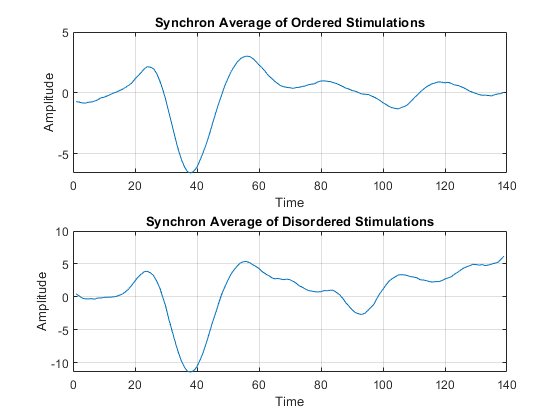

% Zeroing LPF phase shift & applying it on EEG  
LPF = designfilt('lowpassfir', ...        % Response type
       'FilterOrder',15, ...            % Filter order
       'PassbandFrequency',20, ...     % Frequency constraints
       'StopbandFrequency',21, ...
       'SampleRate',250);               % Sample rate
EEG_LPF_FIR = filtfilt(LPF, EEG);

figure(1)
sync_avg(EEG_LPF_FIR, INDF, INDD);

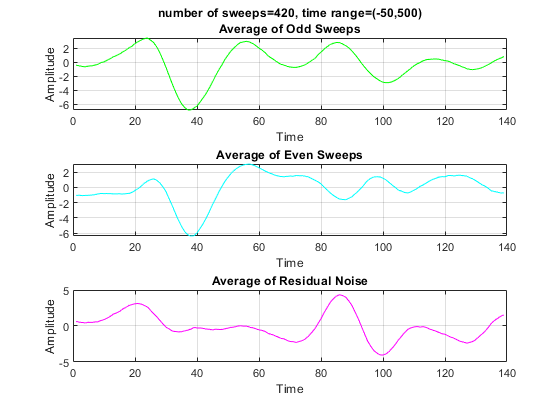

SNR_LP_FIR = 1.1305


figure(2)
[~, ~, ~, SNR_LP_FIR] = SNR_func(EEG_LPF_FIR, INDF, 420, -50, 500)

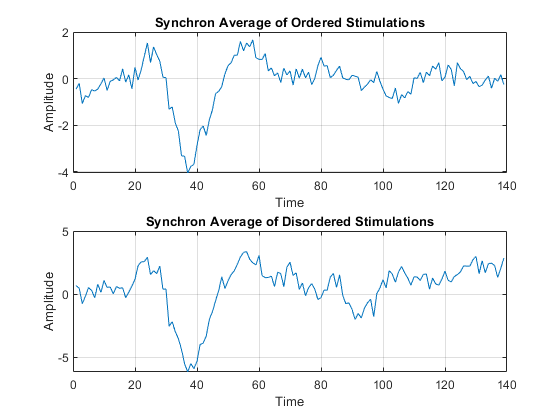


% Zeroing HPF phase shift  & applying it on EEG    
HPF = designfilt('highpassfir', ...       % Response type
       'StopbandFrequency',0.5, ...     % Frequency constraints
       'PassbandFrequency',1, ...
       'PassbandRipple',4, ...    
       'DesignMethod','kaiserwin', ...  % Design method ...
       'SampleRate',250);               % Sample rate
EEG_HPF_FIR = filtfilt(HPF, EEG);

figure(3)
sync_avg(EEG_HPF_FIR, INDF, INDD);

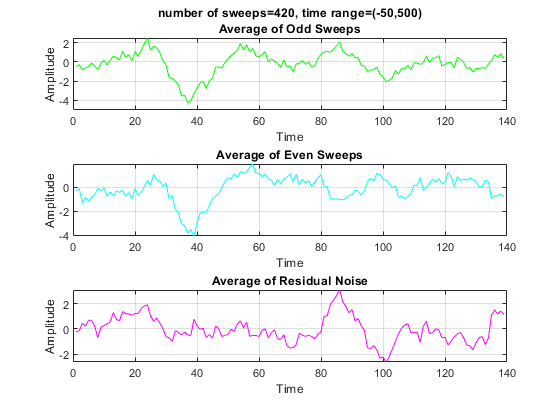

SNR_HP_FIR = 0.9718


figure(4)
[~, ~, ~, SNR_HP_FIR] = SNR_func(EEG_HPF_FIR, INDF, 420, -50, 500)

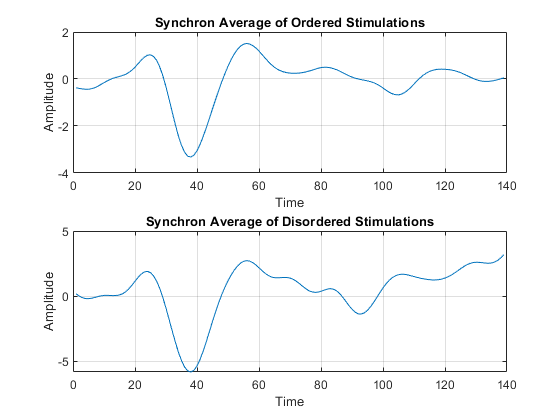


% Zeroing BPF phase shift  & applying it on EEG   
BPF = designfilt('bandpassfir', ...       % Response type
       'FilterOrder',15, ...            % Filter order
       'StopbandFrequency1',0.5, ...    % Frequency constraints
       'PassbandFrequency1',1, ...
       'PassbandFrequency2',20, ...
       'DesignMethod','ls', ...         % Design method ...
       'StopbandFrequency2',21, ...
       'SampleRate',250);               % Sample rate
EEG_BPF_FIR = filtfilt(BPF, EEG);

figure(5)
sync_avg(EEG_BPF_FIR, INDF, INDD);

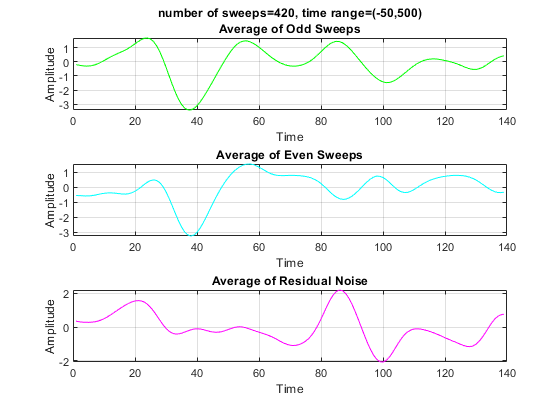

SNR_BP_FIR = 1.1262


figure(6)
[~, ~, ~, SNR_BP_FIR] = SNR_func(EEG_BPF_FIR, INDF, 420, -50, 500)

## IIR filter

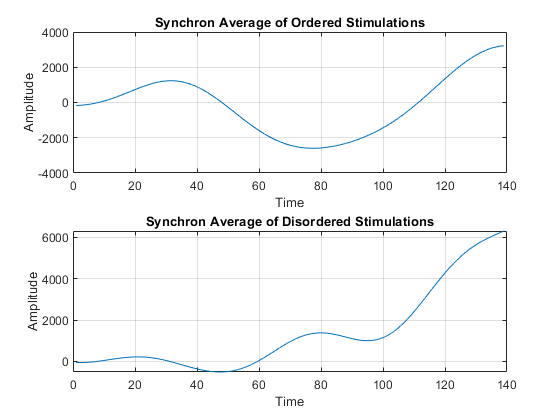

% Zeroing LPF phase shift  & applying it on EEG     
lpf =  designfilt('lowpassiir', ...        % Response type
       'PassbandFrequency',20, ...     % Frequency constraints
       'StopbandFrequency',21, ...
       'SampleRate',250) ;              % Sample rate
EEG_LPF_IIR = filtfilt(lpf, EEG);

figure(7)
sync_avg(EEG_LPF_IIR, INDF, INDD);

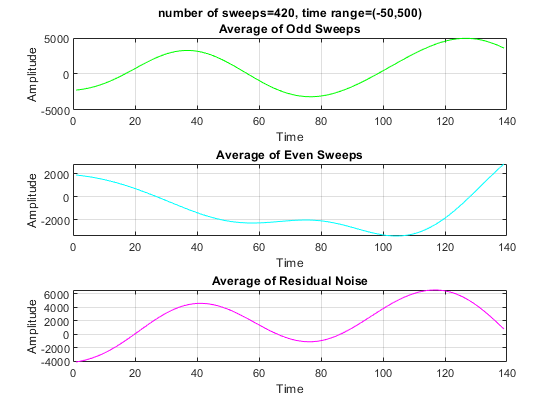

SNR_LP_IIR = 0.3300


figure(8)
[~, ~, ~, SNR_LP_IIR] = SNR_func(EEG_LPF_IIR, INDF, 420, -50, 500)

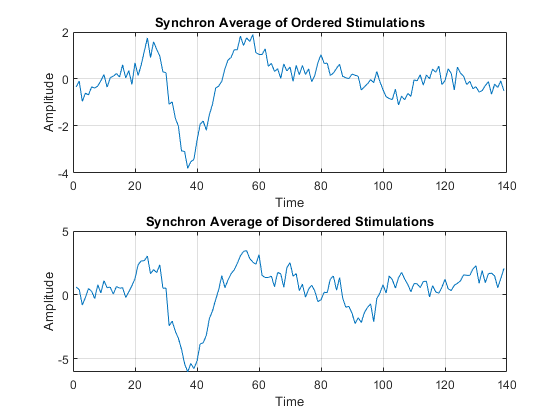


% Zeroing LPF phase shift  & applying it on EEG    
hpf = designfilt('highpassiir', ...       % Response type
       'StopbandFrequency',0.5, ...     % Frequency constraints
       'PassbandFrequency',1, ...
       'StopbandAttenuation',55, ...    % Magnitude constraints
       'PassbandRipple',4, ...
       'SampleRate',250) ;              % Sample rate
EEG_HPF_IIR = filtfilt(hpf, EEG);

figure(9)
sync_avg(EEG_HPF_IIR, INDF, INDD);

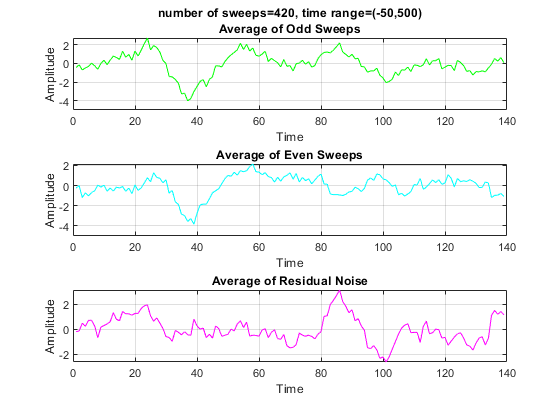

SNR_HP_IIR = 0.9560


figure(10)
[~, ~, ~, SNR_HP_IIR] = SNR_func(EEG_HPF_IIR, INDF, 420, -50, 500)

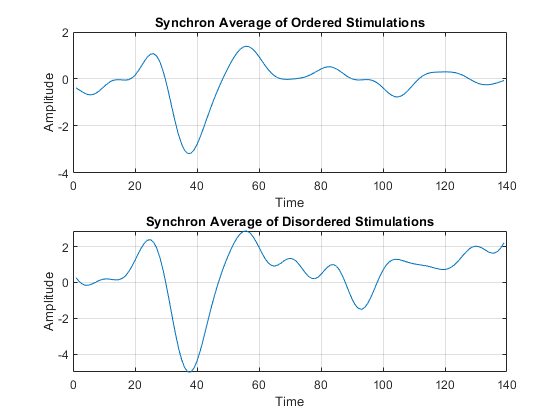


% Applying both LP & HP filters on EEG
bpf = designfilt('bandpassiir', ...       % Response type
       'StopbandFrequency1',0.5, ...    % Frequency constraints
       'PassbandFrequency1',1, ...
       'PassbandFrequency2',20, ...
       'StopbandFrequency2',21, ...
       'StopbandAttenuation1',40, ...   % Magnitude constraints
       'PassbandRipple',1, ...
       'StopbandAttenuation2',50, ...
       'DesignMethod','ellip', ...      % Design method
       'MatchExactly','passband', ...   % Design method options
       'SampleRate',250);               % Sample rate
EEG_BPF_IIR = filtfilt(bpf, EEG);

figure(11)
sync_avg(EEG_BPF_IIR, INDF, INDD);

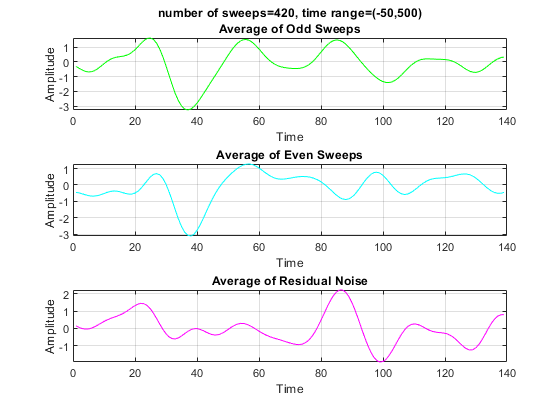

SNR_BP_IIR = 1.0762


figure(12)
[~, ~, ~, SNR_BP_IIR] = SNR_func(EEG_BPF_IIR, INDF, 420, -50, 500)

## SNRs

SNRs = sprintf(['SNR_LP_FIR = %G,\nSNR_HP_FIR = %G,' ...
         '\nSNR_BP_FIR = %G,\nSNR_LP_IIR = %G,' ...
         ' \nSNR_HP_IIR = %G,\nSNR_BP_IIR = %G  '], ...
         SNR_LP_FIR,SNR_HP_FIR, SNR_BP_FIR, ...
         SNR_LP_IIR, SNR_HP_IIR, SNR_BP_IIR)

SNRs =     'SNR_LP_FIR = 1.13052,
     SNR_HP_FIR = 0.971817,
     SNR_BP_FIR = 1.12624,
     SNR_LP_IIR = 0.329952, 
     SNR_HP_IIR = 0.955983,
     SNR_BP_IIR = 1.07617  '
